element level integrations

clear all;
clc

syms x

EA = input('Enter the value of EA:  ');
k = input('spring constant assosciated with the member, k = ');
x_0 = 0 ;
x_L = input('Enter the length of the bar:  ');
nel  = input('Enter the number of elements:  ');

K = zeros(nel+1,nel+1);
F = zeros(nel+1,1);

h = (x_L - x_0)/nel;

x1 = 0:h:(x_L-h);
x2 = h:h:x_L;

while true
    f = input('Distribution (use small letter "x" if it is a variable) of axial force = ')

f =     10


Boundary condition at x = 0

    while true
        type_0 = input('Enter the type of boundary condition(1,2,or3) at x = 0:   ')

        if type_0 == 1
            U_0 = input('Give the displacement at the end x = 0 :  ')
            break
        elseif type_0 == 2
            P_0 = input('Give the force at the end x = 0 :  ')
            break
        elseif type_0 == 3
            k_spring = input('Give the value of connected spring constant :  ') % Please understand the difference between K , k , k_spring
            delta_0 = input('Give the extension of the connected spring at the end x = 0 :  ')
            break
        else
            fprintf('Error, Boundary condition must be any of of type 1 / type 2 or type 3 ')
            continue
        end
    end

type_0 =      2


P_0 =      5


Boundary condition at x = L

    while true
        type_L = input('Enter the type of boundary condition(1,2,or3) at x = L:   ')

        if type_L == 1
            U_L = input('Give the displacement at the end x = L :  ')
            break
        elseif type_L == 2
            P_L = input('Give the force at the end x = L :  ')
            break
        elseif type_L == 3
            k_spring = input('Give the value of connected spring constant :  ') % Please understand the difference between K , k , k_spring
            delta_L = input('Give the extension of the connected spring at the end x = L :  ')
            break
        else
            fprintf('Error, Boundary condition must be any of of type 1 / type 2 or type 3 ')
            continue
        end
    end

type_L =      2


P_L =     10


        if k == 0
        if int(f*(h-x)/h,0,L) + P_L - P_0 == 0
            break
        else
            fprintf('If spring constant assosciated with the member, k = 0, then,\n there must be a force equilibrium balance to have a solution.\n Kindly update the values of forces at both ends and the axial\n distribution of forces accordingly.')
            continue
        end
    else
        break
    end
end


for e = 1:nel

    FF = zeros(2,1);
    KK = zeros(2,2);

    X1 = x1(e);
    X2 = x2(e);

    N1 = (X2 - x)/h;
    N2 = (x - X1)/h;

    N = [N1,N2];
    dN = diff(N);

    for i = 1:2
        FF(i) = FF(i) + int(f*N(i),X1,X2) + subs(P_L*N(i),x,X1) - subs(P_0*N(i),x,X2);
        for j = 1:2
            KK(i,j) = KK(i,j) + int(EA*dN(i)*dN(j) + k*N(1)*N(2),X1,X2);
        end
    end
    for i = 1:2
        ig = e + (i-1);
        F(ig) = F(ig) + FF(i);
        for j = 1:2
            jg = e + (j-1);
            K(ig,jg) = K(ig,jg) + KK(i,j);
        end
    end
end

Alpha = K\F;

for i = 1:nel

    X1 = x1(i);
    X2 = x2(i);

    N1 = (X2 - x)/h;
    N2 = (x - X1)/h;

    U(i) = Alpha(i)*N1 + Alpha(i+1)*N2;
end


`Plotting 

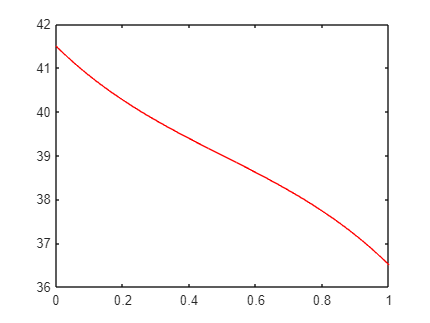

figure();
for i = 1:nel
    t = linspace(x1(i),x2(i),20);
    u = subs(U(i),x,t);
    plot(t,u,'r','Linewidth',0.2);
    hold on
end